# Intro on machine learning (vol II). fMRI.  

**Author**: Javier Ortiz-Tudela (Goethe University)

**Email**: [ortiztudela@psych.uni-frankfurt.de](mailto:ortiztudela@psych.uni-frankfurt.de)

**Created on**: 06/04/2020

**Last update on**: 12/04/2020

## Initialize some stuff.

Just run this section. Press Ctrl + Enter.

clear; close all
clc
load('beta_maps.mat')

## Intoduction

What are beta maps? Slides.

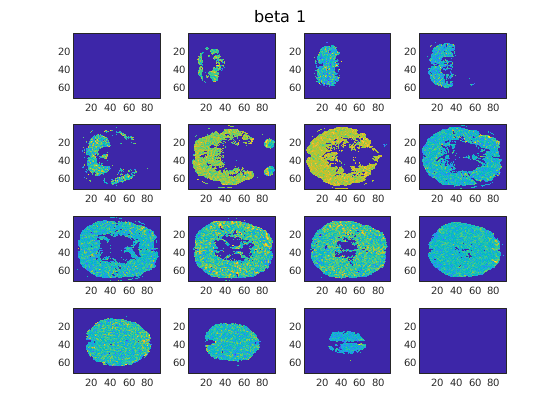

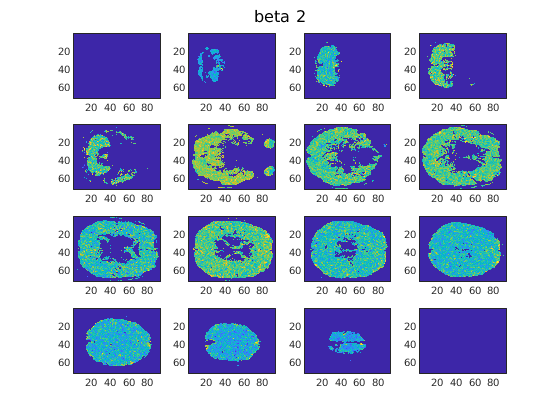

% Visualize two maps
for cBeta=1:2
    figure; c=1;
    for cImage=1:5:size(beta_maps{1},3)
        subplot(4,4,c), imagesc(beta_maps{cBeta}(:,:,cImage));
        c=c+1;sgtitle(['beta ', num2str(cBeta)]);
    end
end

## Feature (i.e., voxels) selection

Select voxels in a mask

for cBeta=1:length(beta_maps)
    sel_voxels(cBeta,:)=beta_maps{cBeta}(v1_mask==1);
end

Unrecognized function or variable 'beta_maps'.

sel_voxels(isnan(sel_voxels))=0;
figure, imagesc(sel_voxels(:,150:200));
xlabel('voxels'); ylabel('regressors (betas)');

Now we already have our observations (betas) times our features (voxels) matrices. Remember, since we have used a LSS approach for estimating our beta maps, we have one beta per trial.

What are the *labels *for each beta (trial). We have 4 different trial types

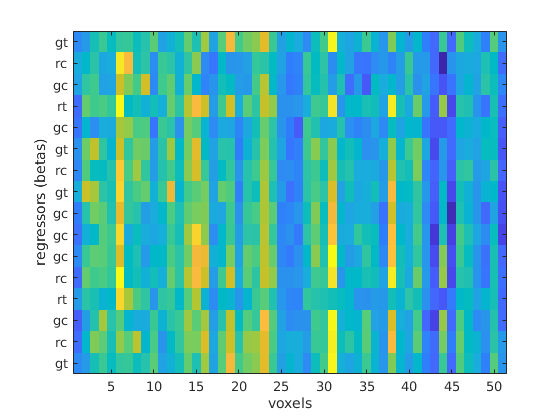

beta_labels={'gt'; 'rc'; 'gc'; 'rt'; 'gc'; 'gt'; 'rc'; 'gt';...
    'gc'; 'gc'; 'gc'; 'rc'; 'rt'; 'gc'; 'rc'; 'gt'};

% Let's visualize them in the previous plot
imagesc(sel_voxels(:,150:200));
xlabel('voxels'); ylabel('regressors (betas)');
yticks(1:16);yticklabels(beta_labels);

## Let's say we want to classify between triangles and circles

We need to re-code our labels to reflect our classification analysis

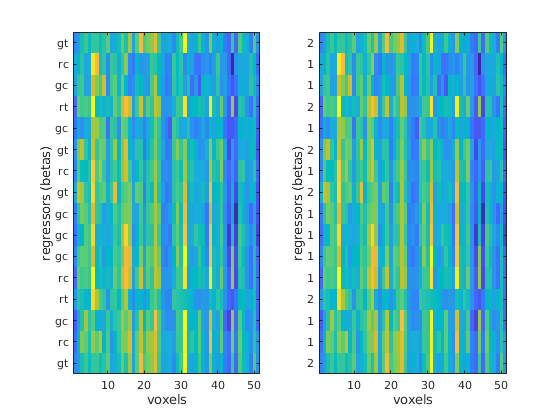

new_labels=zeros(16,1);
new_labels(strcmpi(beta_labels, 'gt'))=2;
new_labels(strcmpi(beta_labels, 'rt'))=2;
new_labels(strcmpi(beta_labels, 'gc'))=1;
new_labels(strcmpi(beta_labels, 'rc'))=1;

% Let's visualize the new labels together with the old ones
subplot(1,2,1), imagesc(sel_voxels(:,150:200)); xlabel('voxels'); ylabel('regressors (betas)');
yticks(1:16);yticklabels(beta_labels);
subplot(1,2,2), imagesc(sel_voxels(:,150:200)); xlabel('voxels'); ylabel('regressors (betas)');
yticks(1:16);yticklabels(new_labels);

## Happy with the coding? We are ready to do the classification.

Let's held out 4 observations for test.

% Get test observations
test_data=sel_voxels(1:4,:);
test_labels=new_labels(1:4);

% Get training observations and their labels
train_data=sel_voxels(5:16,:);
train_labels=new_labels(5:16);

% Train the classifier
classifier = fitcsvm(train_data, train_labels);
% predicted = cosmo_classify_lda(train_data, train_labels, test_data);

% Test the classifier
class_prediction=predict(classifier, test_data);

% Compute performance
shape_acc=mean(class_prediction==test_labels)

shape_acc = 0.2500

## Now we can also ask: 'is the color information coded in our ROI'?

We need to re-code our labels to reflect our classification analysis

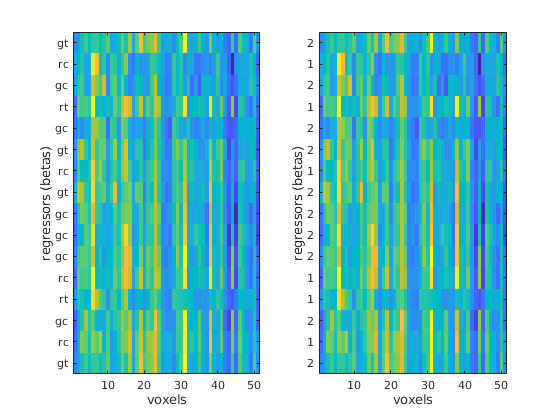

new_labels=zeros(16,1);
new_labels(strcmpi(beta_labels, 'gt'))=2;
new_labels(strcmpi(beta_labels, 'rt'))=1;
new_labels(strcmpi(beta_labels, 'gc'))=2;
new_labels(strcmpi(beta_labels, 'rc'))=1;

% Let's visualize the new labels together with the old ones
subplot(1,2,1), imagesc(sel_voxels(:,150:200)); xlabel('voxels'); ylabel('regressors (betas)');
yticks(1:16);yticklabels(beta_labels);
subplot(1,2,2), imagesc(sel_voxels(:,150:200)); xlabel('voxels'); ylabel('regressors (betas)');
yticks(1:16);yticklabels(new_labels);

## Happy with the coding? We are ready to do the classification.

Get test observations

test_data=sel_voxels(1:4,:);
test_labels=new_labels(1:4);

% Get training observations and their labels
train_data=sel_voxels(5:16,:);
train_labels=new_labels(5:16);

% Train the classifier
classifier = fitcsvm(train_data, train_labels);

% Test the classifier
class_prediction=predict(classifier, test_data);

% Compute performance
color_acc=mean(class_prediction==test_labels)

color_acc = 0.7500